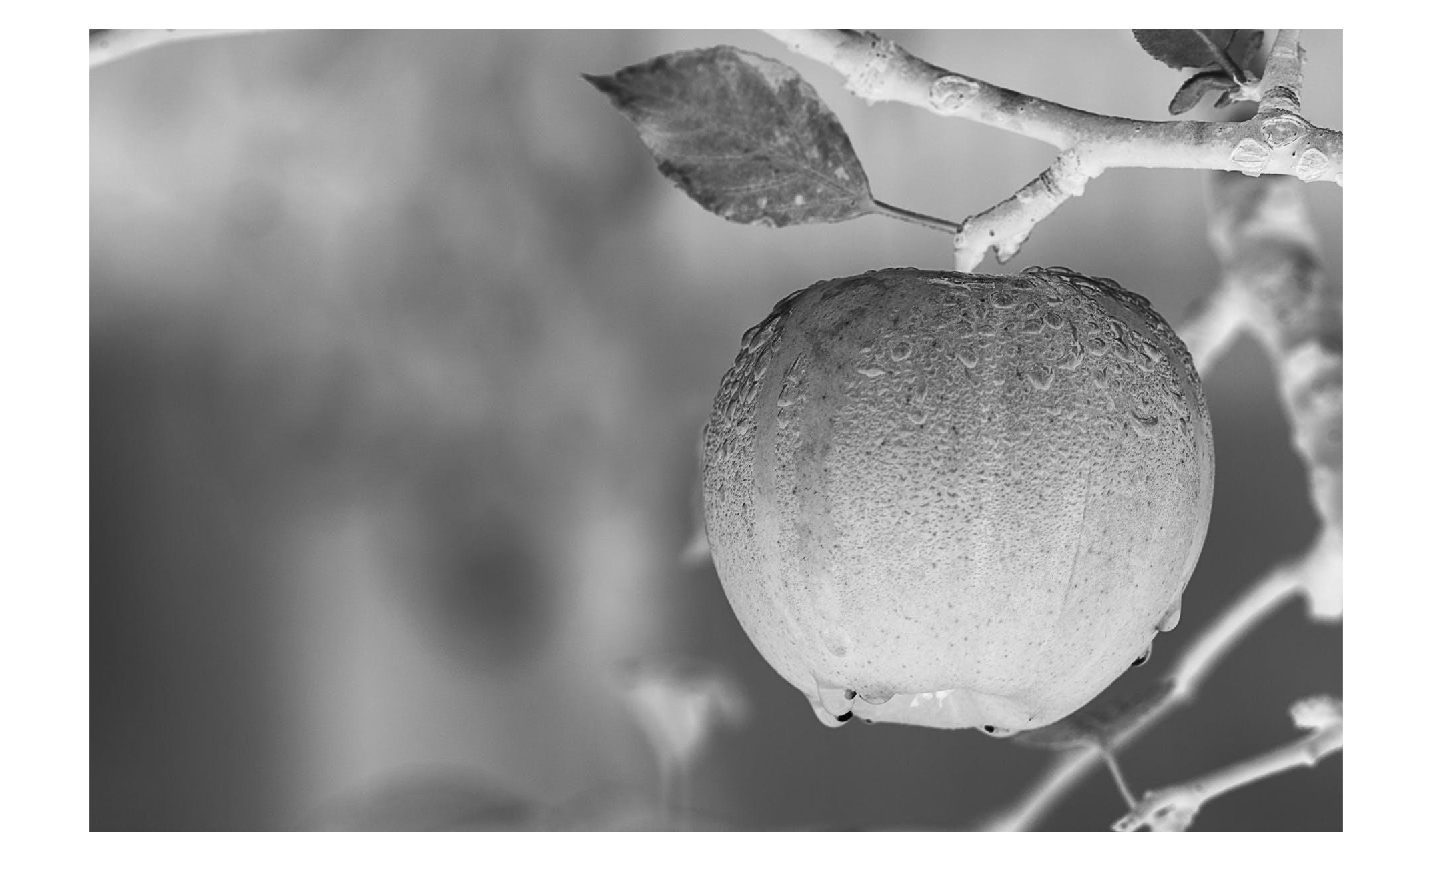

        % PART 2
image = imread('apple.jpg');
K = 7; 
sigma = 3; 
kernel = zeros(K, K);
center = floor(K / 2);
for i = 1:K
    for j = 1:K
        x = i - center;
        y = j - center;
        kernel(i, j) = (1 / (2 * pi * sigma^2)) * exp(-((x^2 + y^2) / (2 * sigma^2)));
    end
end
kernel = kernel / sum(kernel(:));
[m, n] = size(image);
smoothed_image = zeros(m, n);
padded_image = padarray(image, [center center]);
for i = 1:m
    for j = 1:n
        region = padded_image(i:i+K-1, j:j+K-1);
        
        result = kernel .* double(region);
        
        smoothed_image(i, j) = sum(result(:));
    end
end
imshow(image);

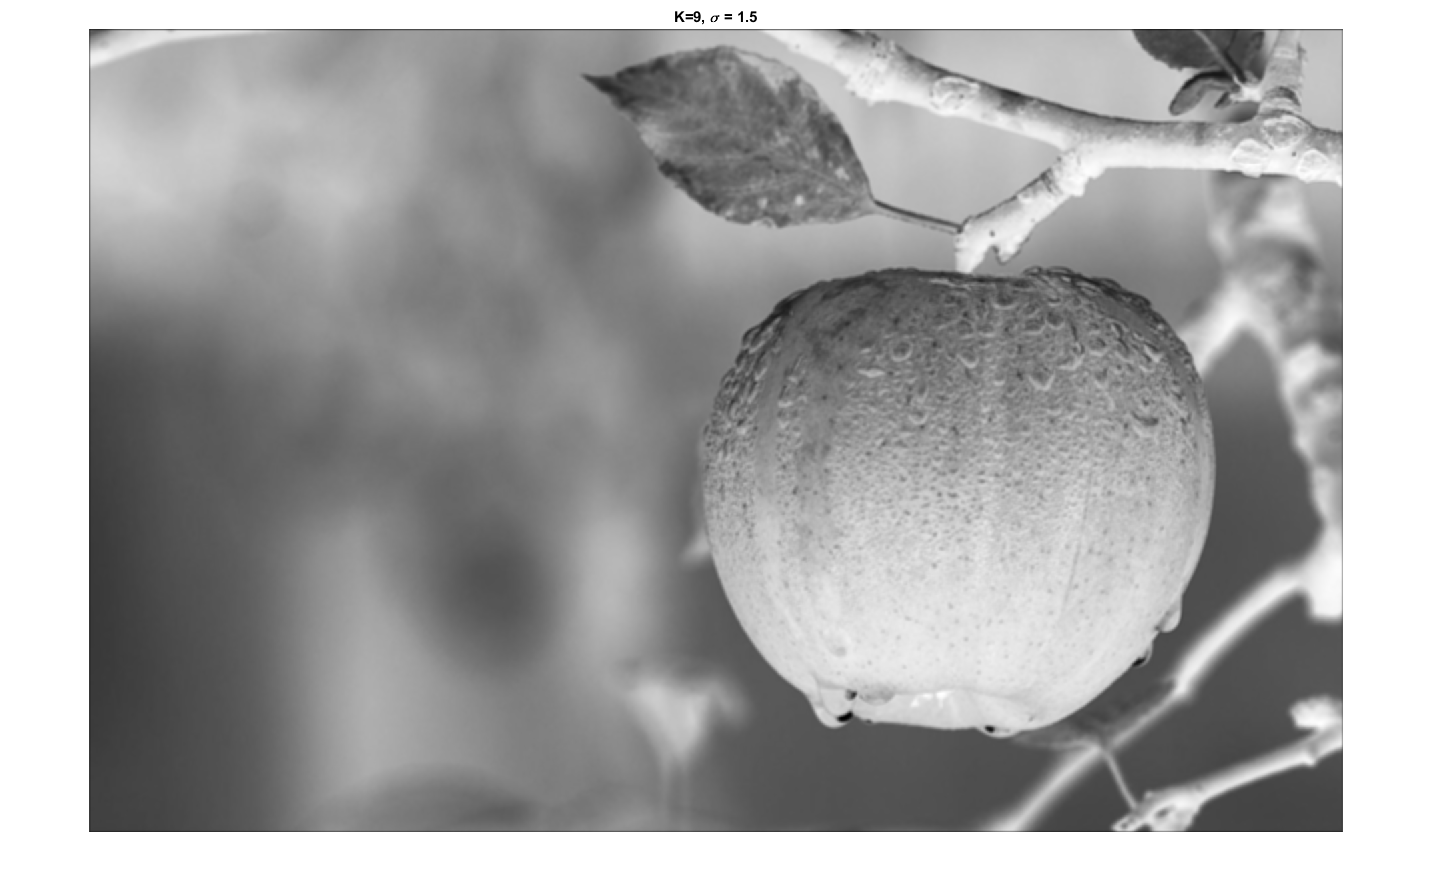

imshow(smoothed_image, []);
title("K=9, \sigma = 1.5")

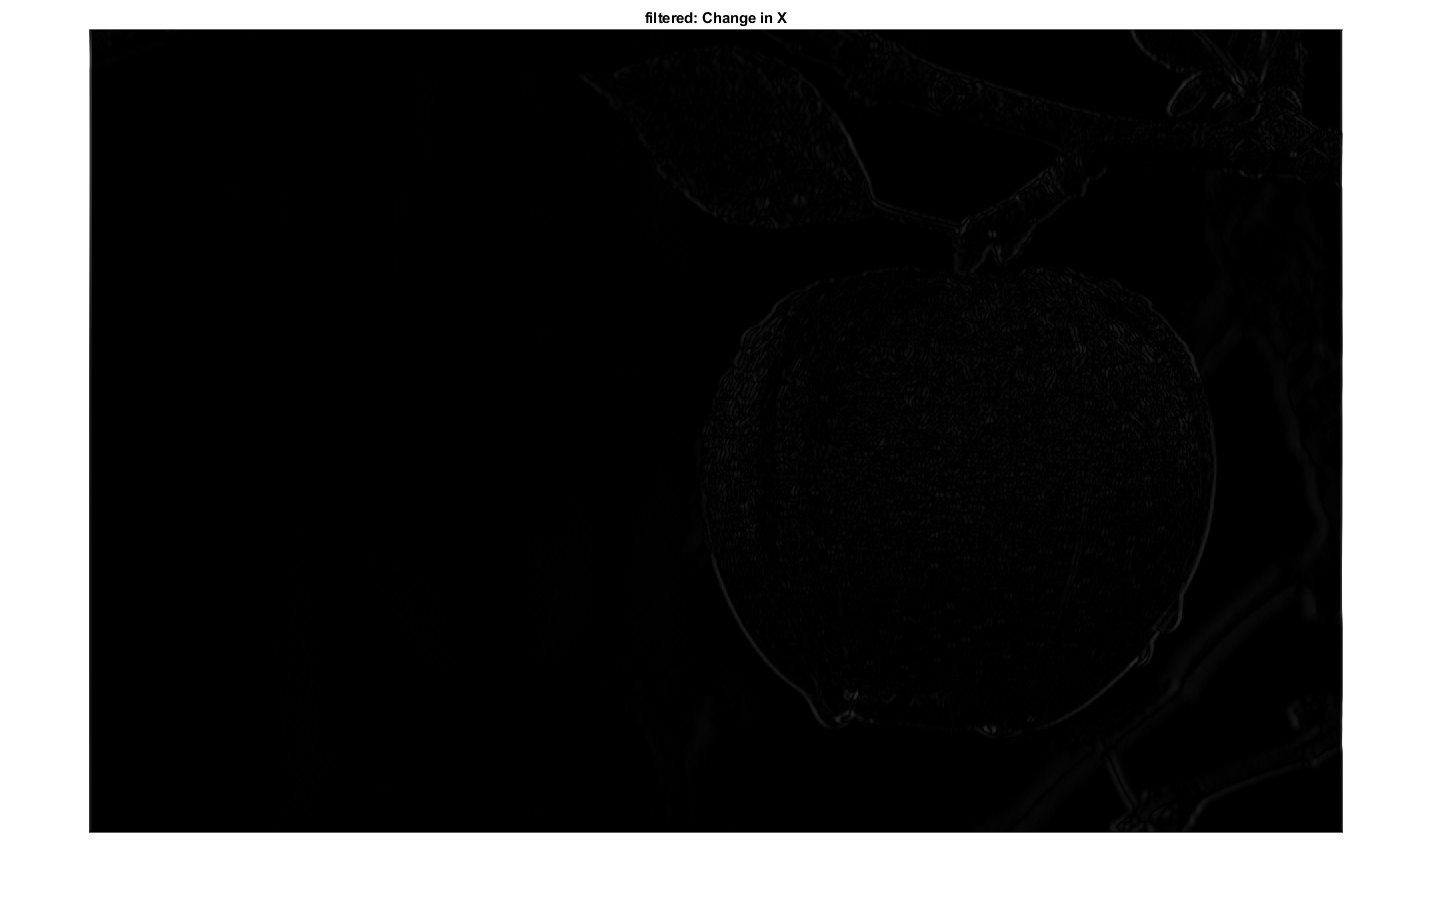


        % PART 3

padded_image = padarray(smoothed_image, [1 1]);

grad_x = double(padded_image(2:end, 1:end-1)) - double(padded_image(2:end, 2:end)); % Change in x direction
grad_y = double(padded_image(1:end-1, 2:end)) - double(padded_image(2:end, 2:end)); % Change in y direction

grad_mag = abs(grad_x) + abs(grad_y);

imshow(abs(grad_x), []);
title('filtered: Change in X')

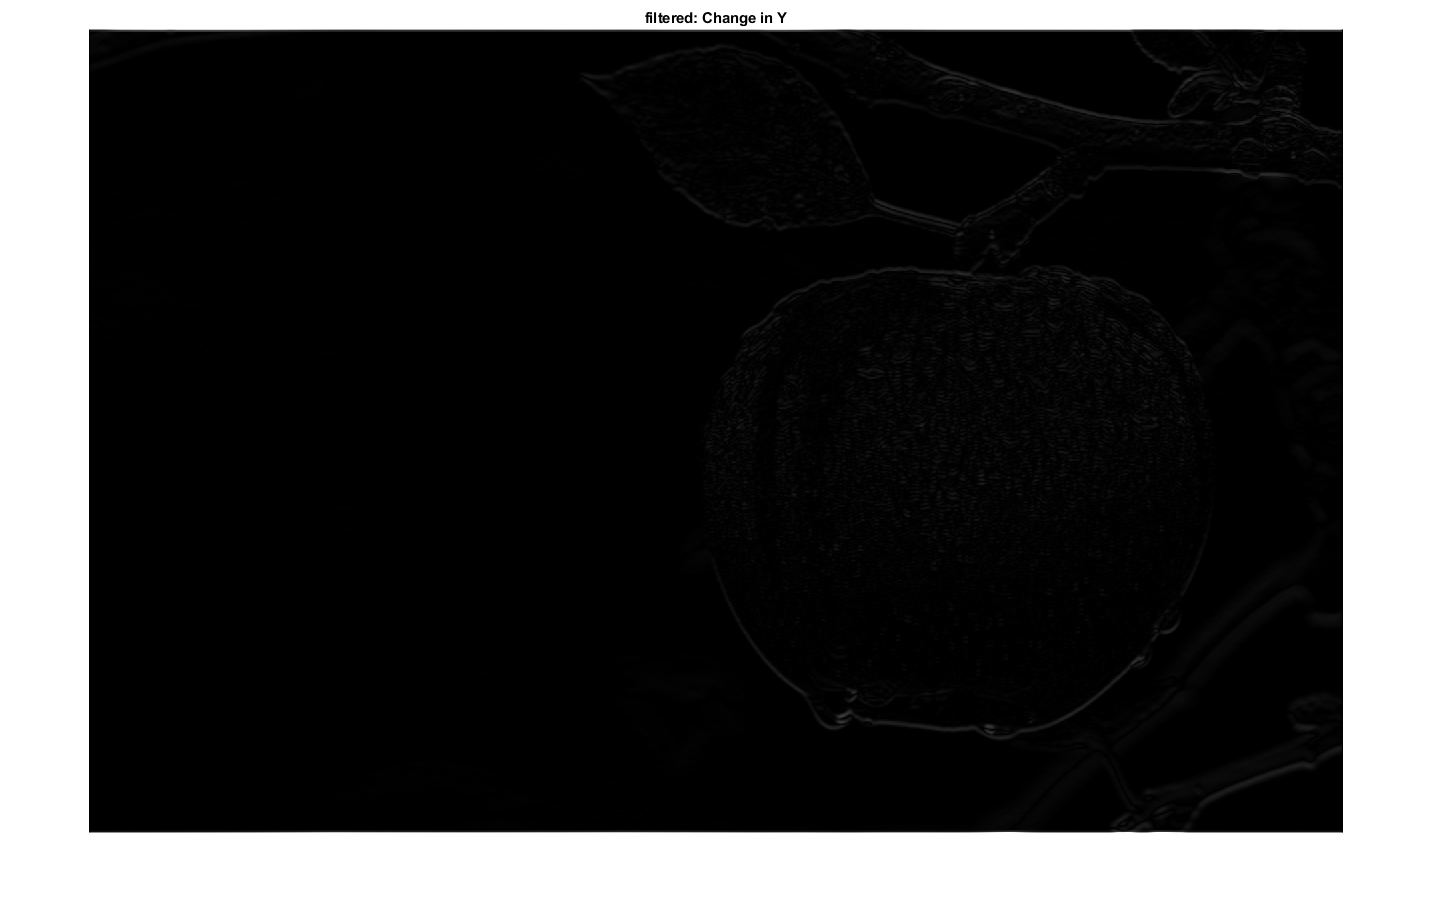


imshow(abs(grad_y), []);
title('filtered: Change in Y')

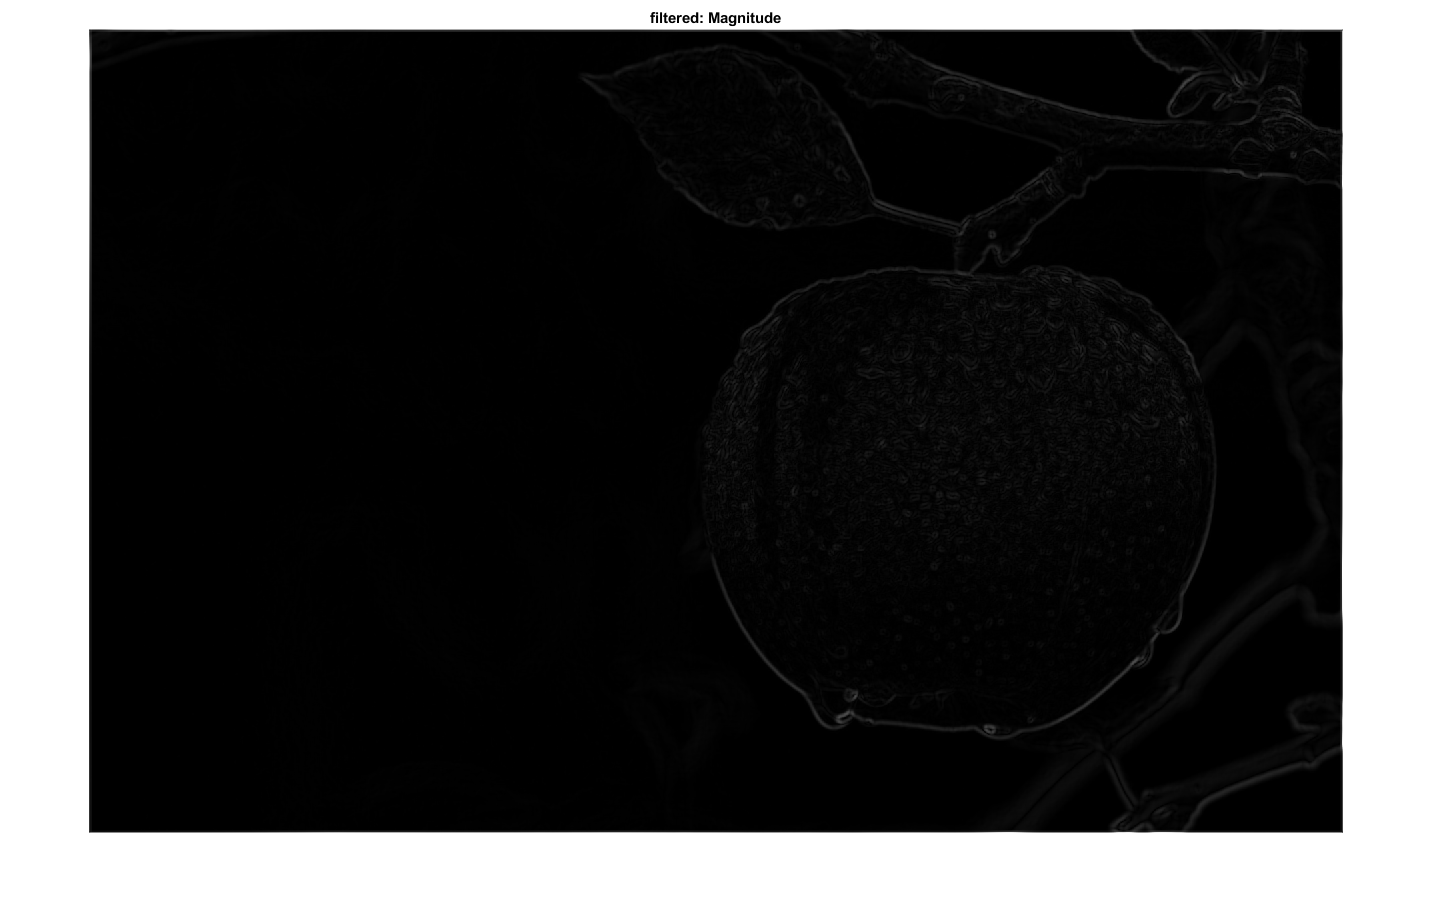

imshow(abs(grad_mag), []);
title('filtered: Magnitude')


output_image = grad_mag;

for i = 2:m-1
    for j = 2:n-1
        angle = grad_angle(i, j);
        magnitude = grad_mag(i, j);
        
        if angle >= -pi/8 && angle < pi/8 % 
            neighbor1 = grad_mag(i, j+1);
            neighbor2 = grad_mag(i, j-1);
        elseif angle >= pi/8 && angle < 3*pi/8 
            neighbor1 = grad_mag(i-1, j+1);
            neighbor2 = grad_mag(i+1, j-1);
        elseif angle >= 3*pi/8 || angle < -3*pi/8 
            neighbor1 = grad_mag(i-1, j);
            neighbor2 = grad_mag(i+1, j);
        else 
            neighbor1 = grad_mag(i-1, j-1);
            neighbor2 = grad_mag(i+1, j+1);
        end
        
        if magnitude < neighbor1 || magnitude < neighbor2
            output_image(i, j) = 0;
        end
    end
end

Index in position 2 exceeds array bounds (must not exceed 641).


figure;
imshow(output_image, []);
title('Non-Maximum Suppression');



% Part 5: Hysterisis
T_L = 0.2 * max(output_image(:));
T_H = 0.5 * max(output_image(:));

binary_image = output_image >= T_H;

while true
    [i, j] = find(binary_image & output_image >= T_L & ~hysteresis_output);
    if isempty(i)
        break; 
    end
    hysteresis_output(sub2ind(size(output_image), i, j)) = 1;
end

figure;
imshow(hysteresis_output, []);
title('Hysteresis Thresholding');



